# BME3053C Final Project: 1D Signal Processing of ECG to Diagnose Arrhythmia 

## Group Name: Glizzy Gators

## Group Members: Jessica Boehlein, Estefania Urrego Hernandez, Tesneem Abdel-latif, Duc Tran

## Course: BME 3053C- Computer Applications for BME

## Term: Fall 2020

## J. Crayton Pruitt Family Department of Biomedical Engineering

## University of Florida

## Email: jboehlein@ufl.edu, estefani.urregoh@ufl.edu, t.abdellatif@ufl.edu, tran.d@ufl.edu

## December 15, 2020

### Load .dat file and display ECG signal

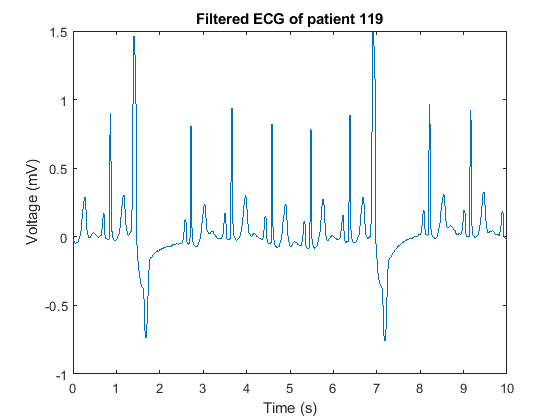

%% function by user "Said BOUREZG" to convert .dat and plot ECG signal
clear all; clc; close all; warning('off','all');
[filename, pathname] = uigetfile('*.dat', 'Open file .dat');% only image Bitmap
if isequal(filename, 0) || isequal(pathname, 0)   
    disp('File input canceled.');  
   ECG_Data = [];  
else
fid=fopen(filename,'r');
end
time=10;
f=fread(fid,2*360*time,'ubit12');
Orig_Sig=f(1:2:length(f));
t=1:length(Orig_Sig);
%% Group work in correcting and labeling axis
t=(10/3600).*t;
% Correct y-axis to fit all ECG into proper voltage signals (mV)
avg=mean(Orig_Sig);
max=max(Orig_Sig);
divVolt=(max-avg)/1.5;
Orig_Sig=(Orig_Sig-avg+15)/divVolt;
% Filter ECG graphs in order to smooth out curves
Filt_Sig = medfilt1(Orig_Sig,12);
plot(t, Filt_Sig)
xlabel('Time (s)');
ylabel('Voltage (mV)');
str='Filtered ECG of patient ';
str=[str filename(1:3)];
title(str);

### Foundation: Initialize and Declare variables

condition=0;
% Calculate BPM by finding count of R-waves multiplied by 6
BPM=length(findpeaks(Filt_Sig,'MinPeakHeight',0.555,'MaxPeakWidth',40))*6;
[~,T]=findpeaks(Filt_Sig,'MinPeakHeight',0.555);
T=(10/3600).*T;
fprintf("The patient's heart beat is %g BPM\n", BPM);

The patient's heart beat is 60 BPM


% Flip the Filtered Signal Graph in order to find troughs of ECG
Flip_Sig=-Filt_Sig;
[~,negT]=findpeaks(Flip_Sig,'MinPeakHeight',0.25);
negT=(10/3600).*negT;
% Variables for RBBB
[RBBBpeaks,RBBBtime]=findpeaks(Filt_Sig,'MinPeakHeight',0.25);
RBBBtime=(10/3600).*RBBBtime;
temp=0;
RBBB=[];

### Check for Irregular Heart Beats

for hh=1:length(RBBBtime)-1
    for jj=1:length(negT)
   prevT=T(T<negT(jj));
   nextT=T(T>negT(jj));
   RBBBneg=negT(negT>RBBBtime(hh));
   % Ensure loop does not give an error
        if isempty(prevT)==1 || isempty(nextT)==1 || isempty(RBBBneg)==1
        break
        end
    % Check for Right Bundle Branch Block (RBBB)
        if RBBBpeaks(hh+1)>RBBBpeaks(hh)+0.055 && RBBBtime(hh+1)-RBBBtime(hh)<0.40 && RBBBneg(1)-RBBBtime(hh)<0.45 && RBBBtime(hh)-temp>0.40
        temp=RBBBtime(hh);
        fprintf('This patient has RBBB at time=%.2fs\n',RBBBtime(hh));
        condition=1;
        RBBB=[RBBB RBBBtime(hh)];
        break
        end
    end
end
temp=0;
    for hh=1:length(RBBBtime)-1
        for jj=1:length(negT)
        prevT=T(T<negT(jj));
        nextT=T(T>negT(jj));
        % Ensure loop does not give an error
        if isempty(prevT)==1 || isempty(nextT)==1
        break
        end
    % Check for Left Bundle Branch Block (LBBB)
         if (negT(jj)-prevT(end)<0.30) && (nextT(1)-negT(jj)<0.30) && negT(jj)-temp>0.30
         temp=negT(jj);
         fprintf('This patient has LBBB at time=%.2fs\n',negT(jj));
         condition=1;
         break
    %Check for Premature Venctricular Contraction (PVC)
        elseif (negT(jj)-prevT(end)<0.30) && (nextT(1)-negT(jj)>0.30) && negT(jj)-temp>0.15
        if isempty(RBBB)==1
         temp=negT(jj);
         fprintf('This patient has PVC at time=%.2fs\n',negT(jj));
         condition=1;
        else
        for ii=1:length(RBBB)
            diff=abs(negT(jj)-RBBB(ii));
            if diff>0.25
                break
            else
         temp=negT(jj);
         fprintf('This patient has PVC at time=%.2fs\n',negT(jj));
         condition=1;
         break
            end
        end
        end
    %Check for Premature Atrial Contraction (APC)
        else
            for ii=1:length(T)-1
                if T(ii+1)-T(ii)<0.4 && T(ii)-prevT(end) >0.6
                fprintf('This patient has APC at time=%.2fs\n',T(ii));
                condition=1;
                break
                end
            break
            end
        end
    end
    end

This patient has PVC at time=1.67s
This patient has PVC at time=7.18s


### Check for bradycardia (slower than normal) and tachycardia (faster than normal)

% Bradycardia is when an adult has a resting heart beat less than 50 beats
% per minute, while tachycardia is with over 100 beats per minute
if BPM<50
    fprintf('This patient is at risk of bradycardia\n');
    condition=1;
elseif BPM>100
    fprintf('This patient is at risk of tachycardia\n');
    condition=1;   
end

### Check if the patient is healthy

if condition==0
    fprintf('This patient is not at risk of arrhythmia\n');
end